 %Numerical Integration

a=0;
b=5;
n=10:10:300;
x=linspace(a,b,100);
f=@(x) exp(x).*sin(4*x);

trap_ints=ones(length(n),1);
for i=1:length(n)
    trap_ints(i)=trap_integral(f,a,b,n(i));
end
simps1_3_int=ones(length(n),1);
for i=1:length(n)
    simps1_3_int(i)=simpsons1_3rule(f,a,b,n(i));
end
simps3_8_int=ones(length(n),1);
for i=1:length(n)
    simps3_8_int(i)=simpsons3_8rule(f,a,b,n(i));
end

romb_iter=10;
romb_int=romberg_integral(f,a,b,romb_iter);


 Romberg Integration table:

     13.5493

    -9.7942   -17.5753

    25.4829    37.2419    40.8964

   -32.1201   -51.3211   -57.2253   -58.7828

   -23.1964   -20.2219   -18.1486   -17.5283   -17.3665

   -15.4387   -12.8528   -12.3615   -12.2697   -12.2491   -12.2441

   -10.9355    -9.4344    -9.2065    -9.1564    -9.1442    -9.1411    -9.1404

    -8.5380    -7.7388    -7.6258    -7.6007    -7.5946    -7.5931    -7.5927    -7.5926

    -7.3034    -6.8919    -6.8354    -6.8229    -6.8198    -6.8191    -6.8189    -6.8188    -6.8188

    -6.6772    -6.4685    -6.4402    -6.4340    -6.4324    -6.4321    -6.4320    -6.4319    -6.4319    -6.4319



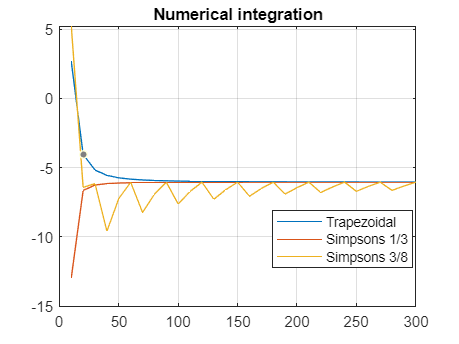


plot(n,trap_ints)
hold on
plot(n,simps1_3_int)
plot(n,simps3_8_int)
hold off
legend('Trapezoidal','Simpsons 1/3','Simpsons 3/8')
title('Numerical integration')
grid on

legend("Position",[0.59325,0.22303,0.30392,0.16361])

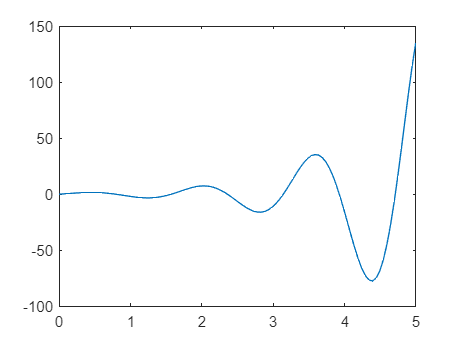


plot(x,f(x))

function int=trap_integral(f,a,b,n)
    dx=(b-a)/n;

    S1=f(a);
    Sn=f(b);

    Sab=0;
    for i =a+dx:dx:b-dx
        Sab=Sab+2*f(i);
    end
    int=(dx/2)*(S1+Sab+Sn);
end

function int=simpsons1_3rule(f,a,b,n)
    dx=(b-a)/n;
    s1=f(a);
    sn=f(b);
    sum_odd=0;
    sum_even=0;
    for i=a+2*dx:2*dx:b-2*dx
        sum_even=sum_even+f(i);
    end
    for i=a+3*dx:2*dx:b-dx
        sum_odd=sum_odd+f(i);
    end

    int=(dx/3)*(s1+4*sum_odd+2*sum_even+sn);
end

function int = simpsons3_8rule(f,a,b,n)
    dx=(b-a)/n;
    s1=f(a);
    sn=f(b);
    s2=0;
    s3=0;
    dxs=a+dx:dx:b-dx;
    for i=1:length(dxs)
        if(mod(i,3) ==0)
            s3=s3+f(a+dxs(i));
        else
            s2=s2+f(a+dxs(i));
        end
    end
    int=(3*dx/8)*(s1+3*s2+2*s3+sn);
end

function int = romberg_integral(f,a,b,n)
    h=b-a;
    r=zeros(2,n+1);
    r(1,1)=(f(a)+f(b))/(2*h);
    fprintf('\n Romberg Integration table:\n');
    fprintf('\n %11.4f\n\n',r(1,1));
    for i=2:n
        sum=0;
        for k=1:2^(i-2)
            sum=sum+f(a+(k-0.5)*h);
        end
        r(2,1)=(r(1,1)+h*sum)/2;

        for j=2:i
            l=2^(2*(j-1));
            r(2,j)=r(2,j-1)+(r(2,j-1)-r(1,j-1))/(l-1);
        end
        for k=1:i
            fprintf('%11.4f',r(2,k));
        end

        fprintf('\n\n');
        h=h/2;
        for j=1:i
            r(1,j)=r(2,j);
        end
    end
    int=r(end,end-1);
end

